# Closed-loop stability analysis using RL plots: Tutorial

#### Arun K. Tangirala

*April 09, 2020*

#### Root Locus Plots

The root locus (RL) plots are essentially a graphical illustration of the roots of a polynomial 


$$F\left(s\right)=1+\beta \;L\left(s\right)$$


as the (design) parameter $\beta \;$is varied mononotonically from its lower to upper extremes. Typically $\beta \in \;\left\lbrack 0,\infty \right)$. 

It is applied to the controller design for determining the admissible range of parameters that results in a stable closed-loop system. The first step is to re-write the characteristic equation of a given CL system in the RL form such that $\beta \;$is the design parameter. $L\left(s\right)$is then read off from the re-written CE. The function $L\left(s\right)$ is also known as the effective open-loop transfer function.

**Second-order system in feedback with P controller:**

The RL for this equation is obtained by first writing the characteristic equation


$$1+K_c G_p \left(s\right)-0$$


Comparing with the standard RL form, we have $\beta =K_c$ and $L\left(s\right)=G_{p\;} \left(s\right)$.

% Process
tau_n = 10;
zeta = 0.7;
Kp = 2;
Gp = tf(Kp,[tau_n^2 2*zeta*tau_n 1]);

% P-controller
Kc = 4

Kc = 4

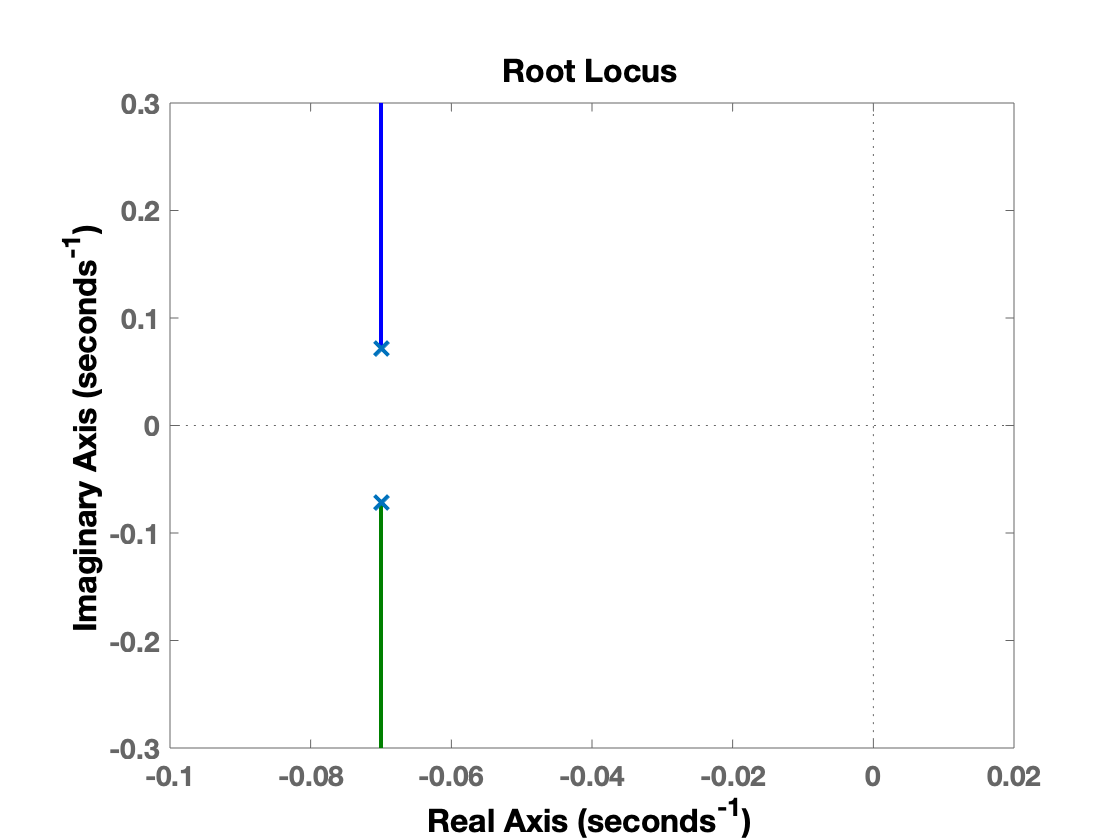

Gc = tf(Kc,1);

% Effective OL system
Ls = Gp;
hrl = rlocusplot(Ls);
hstr_rl = getoptions(hrl);
hstr_rl.Title.FontSize = 16;
hstr_rl.XLabel.FontSize = 16;
hstr_rl.XLabel.FontWeight = 'bold';
hstr_rl.YLabel.FontSize = 16;
hstr_rl.YLabel.FontWeight = 'bold';
hstr_rl.TickLabel.FontSize = 14;
hstr_rl.TickLabel.FontWeight = 'bold';
setoptions(hrl,hstr_rl)
grid off

a_rl = findobj(gca,'type','line');
set(a_rl,'Linewidth',2,'Markersize',8)

**Second-order system in feedback with PI controller**

Turning to the second example where the same second-order system is in feedback with a PI controller, parametrized as $G_c \left(s\right)=K_P^{\prime } +\frac{K_I }{s}$, we have two design parameters, ${K^{\prime } }_P$ and $K_I$.

Standard root locus plots allow us to analyze systems with a single design parameter only. From R-H test, we know that any value of $K_c$ s.t. ${K^{\prime } }_P K_p >0$ is admissible. Therefore, we can select a value of ${K^{\prime } }_P$, say ${K^{\prime } }_P =4$ (generally we select this value based on some performance considerations) and examine the root locus with $K_I$ as the design parameter.

% Process
tau_n = 10;
zeta = 0.7;
Kp = 2;
s = tf('s');
Gp_num = Kp;
Gp_den = 100*s^2 + 14*s + 1;

% PI controller
Kp_con = 4.5

Kp_con = 4.5000

KI = 2.3

KI = 2.3000

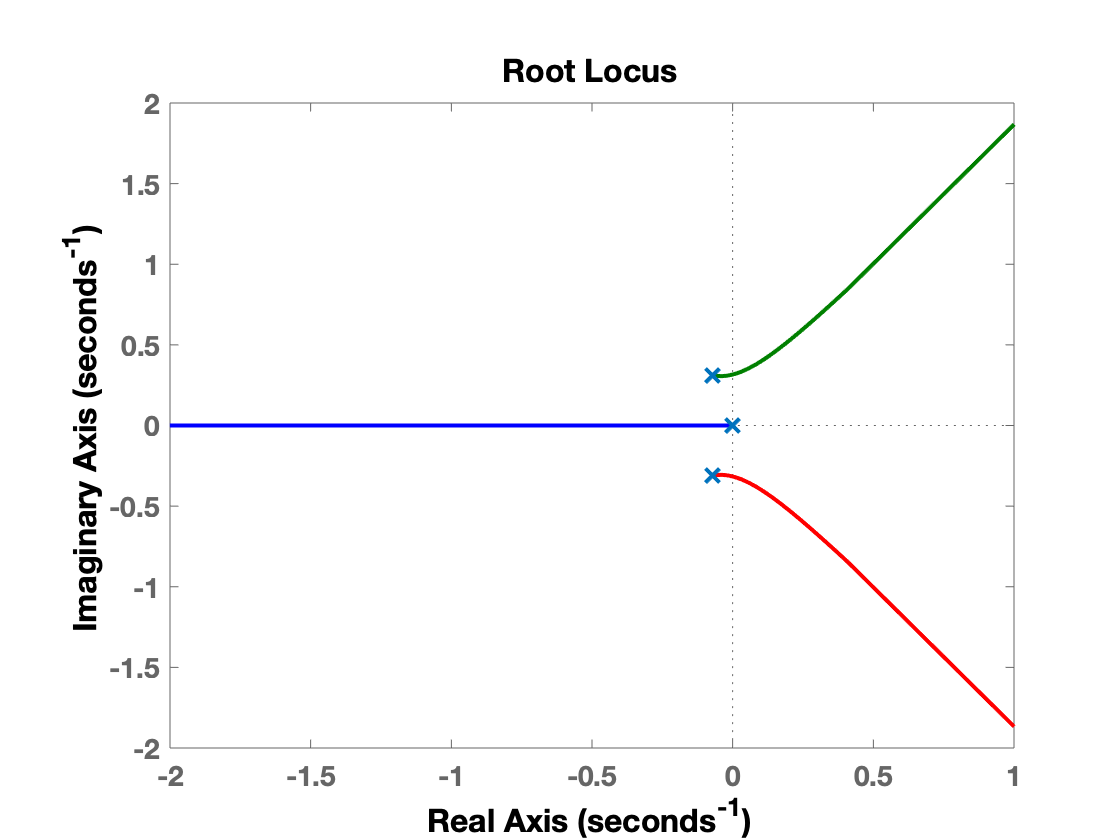

Gc_pi = tf([Kp_con KI],[1 0]);

% Effective OL system with KI as parameter
%Ls = tf(Kp,[tau_n^2 2*zeta*tau_n (1 + Kp*Kp_con) 0]);
Ls = Gp_num/(s*(Gp_den + Kp_con*Gp_num));
hrl = rlocusplot(Ls);
hstr_rl = getoptions(hrl);
hstr_rl.Title.FontSize = 16;
hstr_rl.XLabel.FontSize = 16;
hstr_rl.XLabel.FontWeight = 'bold';
hstr_rl.YLabel.FontSize = 16;
hstr_rl.YLabel.FontWeight = 'bold';
hstr_rl.TickLabel.FontSize = 14;
hstr_rl.TickLabel.FontWeight = 'bold';
setoptions(hrl,hstr_rl)

a_rl = findobj(gca,'type','line');
set(a_rl,'Linewidth',2,'Markersize',8)

#### Second-order system with a zero

Consider the following second-order system with a zero


$$G_p \left(s\right)=\frac{2\left(2s+1\right)}{100s^2 +14s+1}\;$$


placed in feedback with a proportional controller $G_c \left(s\right)=K_c$. The RL form for this scenario is given by

$1+K_c L\left(s\right)=0$ where $L\left(s\right)=\frac{2\left(2s+1\right)}{100s^2 +14s+1}$

The "open-loop" system $L\left(s\right)$ has two complex-valued poles and a zero at $s=-0\ldotp 5$.

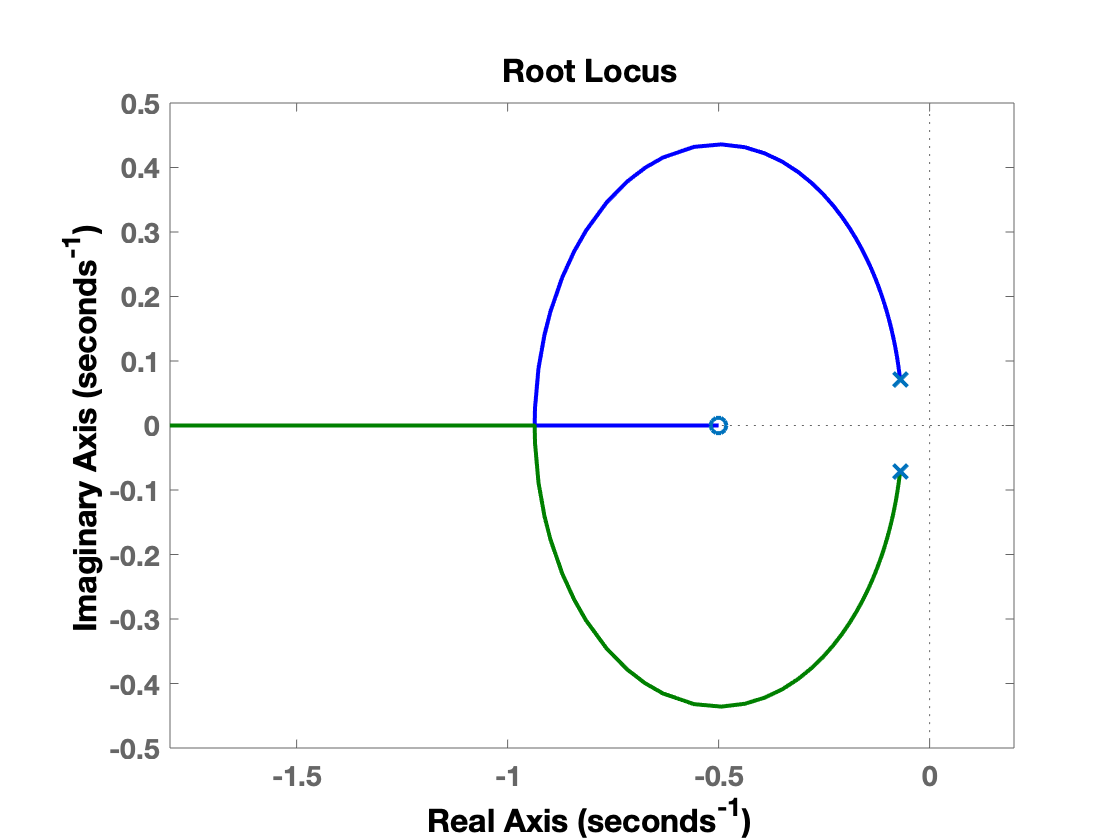

% Process
tau_n = 10;
zeta = 0.7;
Kp = 2;
tau_num = 2;
Gp_2 = tf(Kp*[tau_num 1],[tau_n^2 2*zeta*tau_n 1]);

% Effective OL system with Kc as parameter
Ls = Gp_2;
hrl = rlocusplot(Ls);
hstr_rl = getoptions(hrl);
hstr_rl.Title.FontSize = 16;
hstr_rl.XLabel.FontSize = 16;
hstr_rl.XLabel.FontWeight = 'bold';
hstr_rl.YLabel.FontSize = 16;
hstr_rl.YLabel.FontWeight = 'bold';
hstr_rl.TickLabel.FontSize = 14;
hstr_rl.TickLabel.FontWeight = 'bold';
setoptions(hrl,hstr_rl)

a_rl = findobj(gca,'type','line');
set(a_rl,'Linewidth',2,'Markersize',8)

In order to understand the effect of RHP zero, consider the second-order system with the same gain as above, but with zero at $z_1 =0\ldotp 5$.


$$G_p \left(s\right)=\frac{2\left(2s-1\right)}{100s^2 +14s+1}$$


Notice now that the gain of the system has changed sign. If the gain is to be preserved, the numerator has to be adjusted accordingly. 

The RL is obtained as follows.

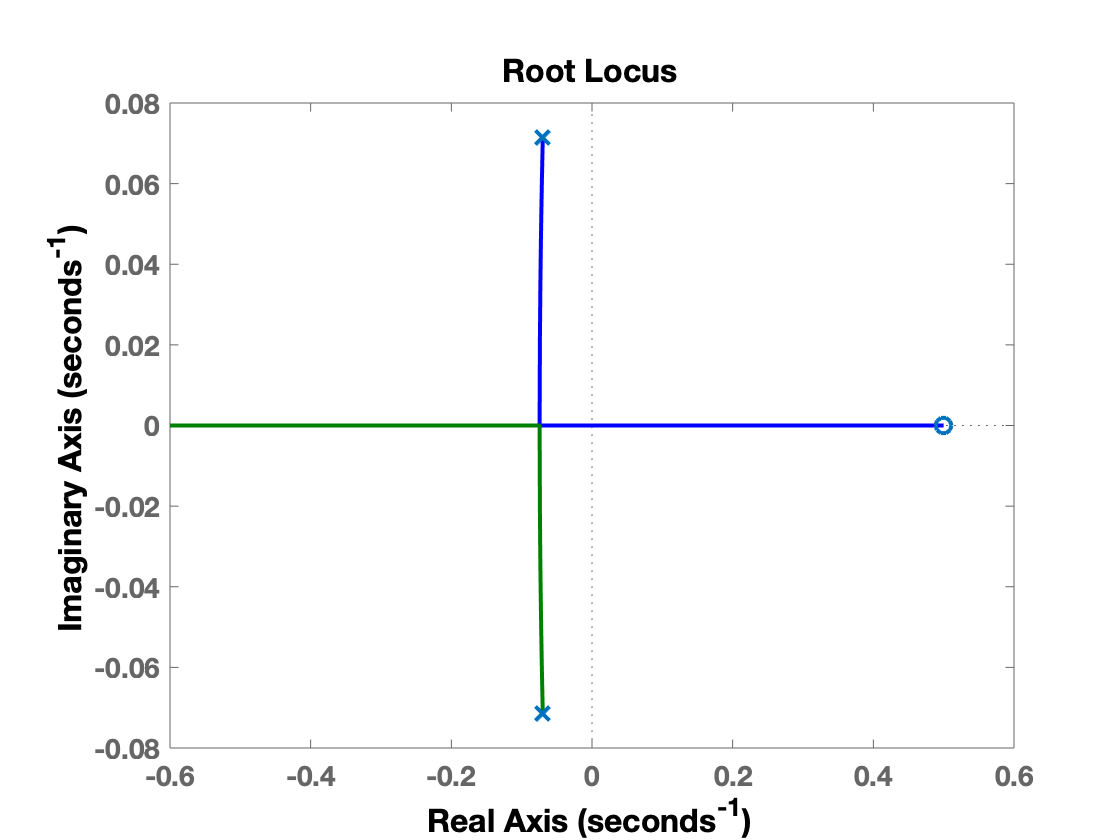

% Process
tau_n = 10;
zeta = 0.7;
Kp = 2;
tau_num = 2;
Gp_3 = tf(Kp*[tau_num -1],[tau_n^2 2*zeta*tau_n 1]);

% Effective OL system with Kc as parameter
Ls = Gp_3;
hrl = rlocusplot(Ls);
hstr_rl = getoptions(hrl);
hstr_rl.Title.FontSize = 16;
hstr_rl.XLabel.FontSize = 16;
hstr_rl.XLabel.FontWeight = 'bold';
hstr_rl.YLabel.FontSize = 16;
hstr_rl.YLabel.FontWeight = 'bold';
hstr_rl.TickLabel.FontSize = 14;
hstr_rl.TickLabel.FontWeight = 'bold';
setoptions(hrl,hstr_rl)

a_rl = findobj(gca,'type','line');
set(a_rl,'Linewidth',2,'Markersize',8)

On the other hand, if we had adjusted the numerator such that both the second-order systems, i.e., one with the LHP and the other with RHP had the same gain, the root locus would be the mirror image of what we saw earlier as seen from the plot generated using the code below.

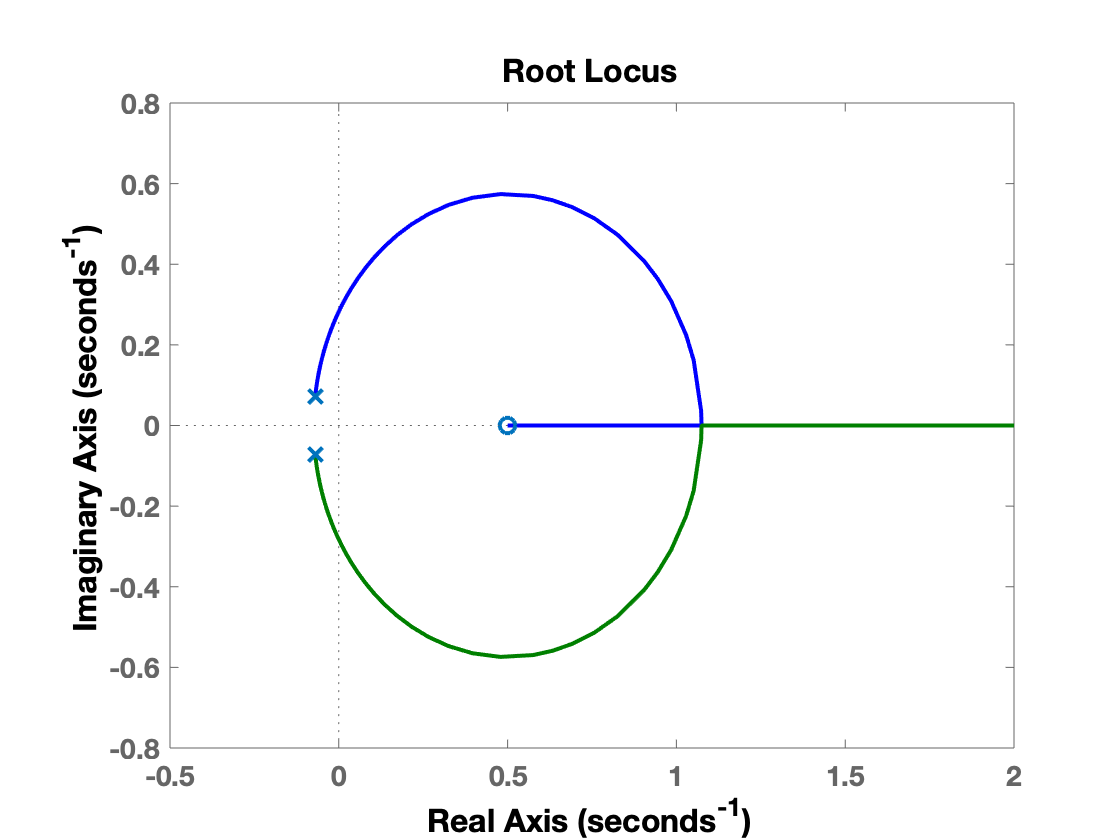

% Process
tau_n = 10;
zeta = 0.7;
Kp = 2;
tau_num = 2;
Gp_4 = tf(Kp*[-tau_num 1],[tau_n^2 2*zeta*tau_n 1]);

% Effective OL system with Kc as parameter
Ls = Gp_4;
hrl = rlocusplot(Ls);
hstr_rl = getoptions(hrl);
hstr_rl.Title.FontSize = 16;
hstr_rl.XLabel.FontSize = 16;
hstr_rl.XLabel.FontWeight = 'bold';
hstr_rl.YLabel.FontSize = 16;
hstr_rl.YLabel.FontWeight = 'bold';
hstr_rl.TickLabel.FontSize = 14;
hstr_rl.TickLabel.FontWeight = 'bold';
setoptions(hrl,hstr_rl)

a_rl = findobj(gca,'type','line');
set(a_rl,'Linewidth',2,'Markersize',8)

Finally, let us place the previous second-order system (with a zero in the LHP) 


$$G_p \left(s\right)=\frac{2\left(2s+1\right)}{100s^2 +14s+1}$$
 

in feedback with a PI controller


$$G_c \left(s\right)=K_P \prime +\frac{K_I }{s}$$
        

The characteristic equation is 


$$1+G_c \left(s\right)G_p \left(s\right)=0$$


Once again, focussing on $K_I$as the design parameter, we have the RL form:


$$1+K_I \frac{2\left(2s+1\right)}{100s^3 +\left(4{K_P }^{\prime } +14\right)s^2 +\left(2{K_P }^{\prime } +1\right)s}=0$$


thereby the effective OL system being 


$$L\left(s\right)=$$

$$\frac{2\left(2s+1\right)}{100s^3 +\left(4{K_P }^{\prime } +14\right)s^2 +\left(2{K_P }^{\prime } +1\right)s}$$


The RL plot for this system is generated using the code below.

% Process
tau_n = 10;
zeta = 0.7;
Kp = 2;
tau_num = 2;
s = tf('s');
Gp_num = 2*(2*s+1);
Gp_den = 100*s^2 + 14*s + 1;

% PI controller
Kp_con = 4.5

Kp_con = 4.5000

KI = 2.3

KI = 2.3000

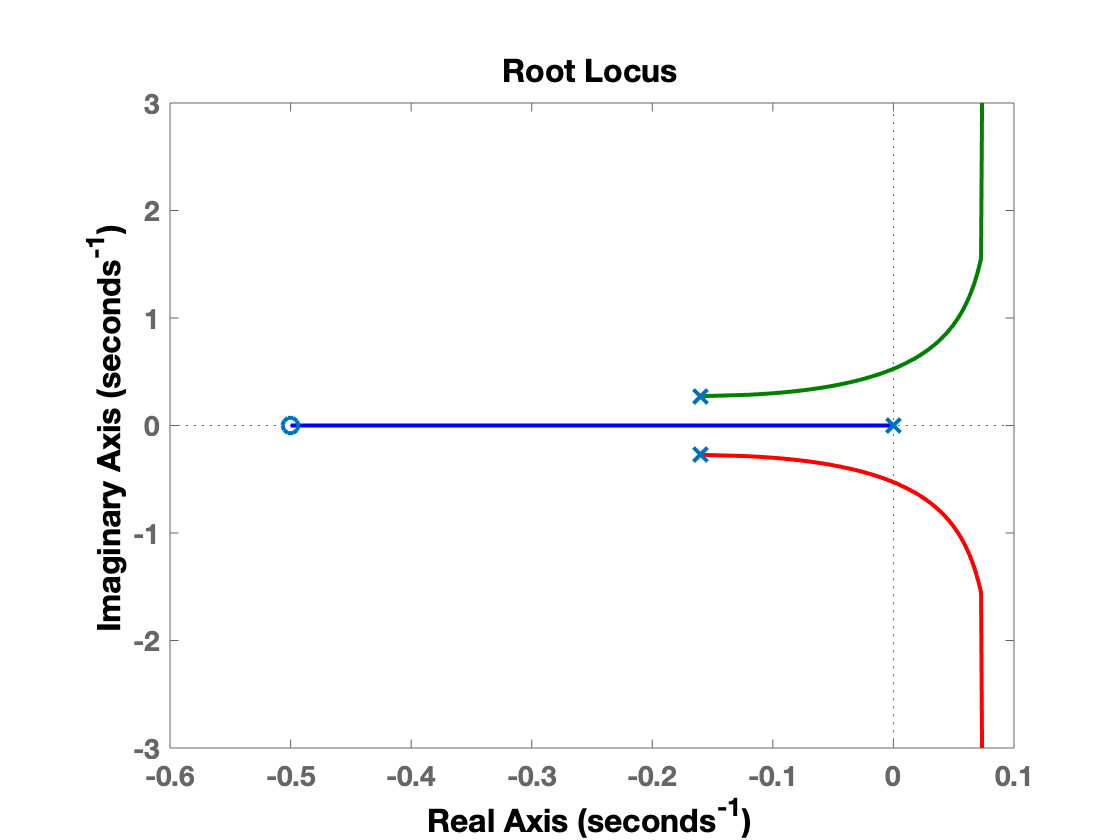

Gc_pi = tf([Kp_con KI],[1 0]);

% Effective OL system with KI as parameter
Ls = Gp_num/(s*(Gp_den + Kp_con*Gp_num));
hrl = rlocusplot(Ls);
hstr_rl = getoptions(hrl);
hstr_rl.Title.FontSize = 16;
hstr_rl.XLabel.FontSize = 16;
hstr_rl.XLabel.FontWeight = 'bold';
hstr_rl.YLabel.FontSize = 16;
hstr_rl.YLabel.FontWeight = 'bold';
hstr_rl.TickLabel.FontSize = 14;
hstr_rl.TickLabel.FontWeight = 'bold';
setoptions(hrl,hstr_rl)

a_rl = findobj(gca,'type','line');
set(a_rl,'Linewidth',2,'Markersize',8)